# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 최세영 **

**학번**** : 201716334**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

xn = [1,2,2,1]; N=4; X = dft(xn,N)

WN = 0.0000 - 1.0000i

X =    6.0000 + 0.0000i  -1.0000 - 1.0000i   0.0000 - 0.0000i  -1.0000 + 1.0000i


xn = [1,2,2,1]; N=4; X = idft(xn,N)

WN = 0.0000 - 1.0000i

X =    1.5000 + 0.0000i  -0.2500 + 0.2500i   0.0000 + 0.0000i  -0.2500 - 0.2500i


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

xn = [0,0,0,0,0,0,0,0,0,0,0,0,1,2,2,1]; N=16; X = dft(xn,N)

WN = 0.9239 - 0.3827i

X =    6.0000 + 0.0000i   3.1035 + 4.6447i  -1.7071 + 4.1213i  -2.8793 + 0.5727i  -1.0000 - 1.0000i   0.0509 - 0.2557i  -0.2929 + 0.1213i  -0.2750 - 0.1838i   0.0000 + 0.0000i  -0.2750 + 0.1838i  -0.2929 - 0.1213i   0.0509 + 0.2557i  -1.0000 + 1.0000i  -2.8793 - 0.5727i  -1.7071 - 4.1213i   3.1035 - 4.6447i


xn = [0,0,0,0,0,0,0,0,0,0,0,0,1,2,2,1]; N=16; X = idft(xn,N)

WN = 0.9239 - 0.3827i

X =    0.3750 + 0.0000i   0.1940 - 0.2903i  -0.1067 - 0.2576i  -0.1800 - 0.0358i  -0.0625 + 0.0625i   0.0032 + 0.0160i  -0.0183 - 0.0076i  -0.0172 + 0.0115i   0.0000 - 0.0000i  -0.0172 - 0.0115i  -0.0183 + 0.0076i   0.0032 - 0.0160i  -0.0625 - 0.0625i  -0.1800 + 0.0358i  -0.1067 + 0.2576i   0.1940 + 0.2903i


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

xn = [4,1,-1,1]; N = 4; X = dfs(xn,N)

WN = 0.0000 - 1.0000i

X =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

xn = [1,0,-1,-1,0]; N = 5; Xk = dfs(xn,N)

WN = 0.3090 - 0.9511i

Xk =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

n = 0:100; 
xn = sinc((n-50)/2).^2; 
N = length(xn);
Xk = dft(xn,N); k = 0:N-1; 

WN = 0.9981 - 0.0622i

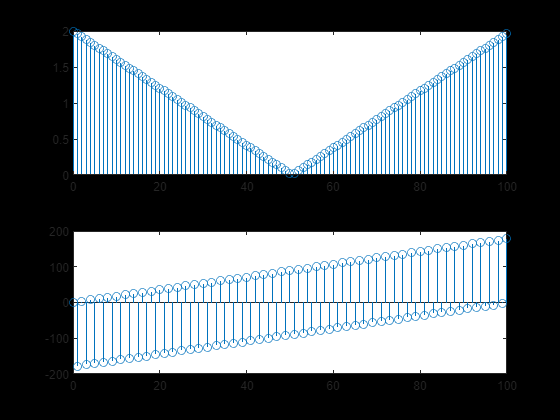

mag_1= abs(Xk); pha_1= angle(Xk)*180/pi; 

subplot(2,1,1); stem(k,mag_1); 

subplot(2,1,2); stem(k,pha_1); 

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

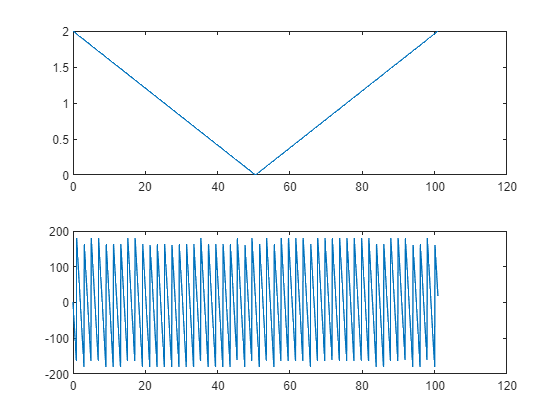

[X,w] = freqz(xn,1,1000, 'whole');
mag_2 = abs(X); pha_2= angle(X)*180/pi; 
Dw = (2*pi)/N; 
subplot(2,1,1); plot(w/Dw,mag_2); 
subplot(2,1,2); plot(w/Dw,pha_2);

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

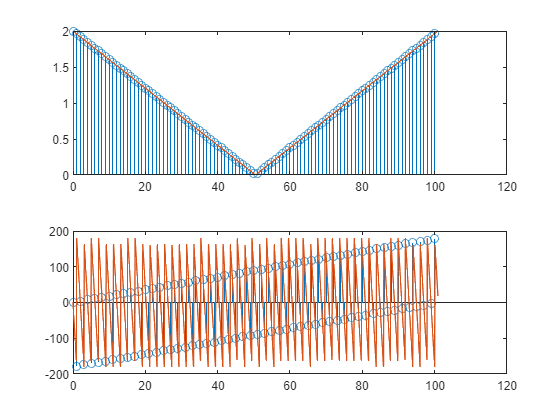

subplot(2,1,1); stem(k,mag_1); hold on
subplot(2,1,2); stem(k,pha_1); hold on
subplot(2,1,1); plot(w/Dw,mag_2); 
subplot(2,1,2); plot(w/Dw,pha_2);

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

       재구성 할 수 있다.

function [Xk] = dfs(xn,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N)
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;

end


function [xn] = idft(Xk,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N)
nk = n'*k;
WNnk = WN .^ (-nk);
xn = (Xk * WNnk)/N;

end

function [Xk] = dft(xn,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N)
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;

end